clear all
close all
clc

currentFolder='//Users/hannahfarnsworth/Dropbox (HMS)/hyperdata';
cd(currentFolder)

load masterStackTable.mat

**Making Histogram**

Getting Ages

currentFolder='//Users/hannahfarnsworth/Dropbox (HMS)/hyperdata';
cd(currentFolder)

load CompiledPhysio_final.mat

UniqueIds=cell2table(unique(alldataV.Master_ID));
masterIDs=cell2table(masterID.Master_ID)

AgeIndex=ismember(masterIDs,UniqueIds)
Age=array2table(masterID.AgeAtExp_InjectionStart_days_(AgeIndex))

masterIDs = 261×1 table
     Var1  
    _______

    {'H1' }
    {'H2' }
    {'H3' }
    {'H4' }
    {'H5' }
    {'H6' }
    {'H7' }
    {'H8' }
    {'H9' }
    {'H10'}
    {'H11'}
    {'H12'}
    {'H13'}
    {'H14'}
    {'H15'}
    {'H16'}


Age.Properties.VariableNames= {'Age'}
AgeID=cell2table(masterIDs.Var1(AgeIndex))

AgeIndex = 261×1 logical array
   1
   1
   1
   1
   1
   1
   1
   0
   1
   1


AgeID.Properties.VariableNames={'Master_ID'}

Age = 235×1 table
    Var1
    ____

     63 
     63 
     63 
     63 
     67 
     67 
     67 
     61 
     61 
     46 
     46 
     46 
     46 
     68 
     68 
     69 


NewAgeIDs=[AgeID, Age]

Age = 235×1 table
    Age
    ___

    63 
    63 
    63 
    63 
    67 
    67 
    67 
    61 
    61 
    46 
    46 
    46 
    46 
    68 
    68 
    69 


AgeID = 235×1 table
     Var1  
    _______

    {'H1' }
    {'H2' }
    {'H3' }
    {'H4' }
    {'H5' }
    {'H6' }
    {'H7' }
    {'H9' }
    {'H10'}
    {'H15'}
    {'H16'}
    {'H17'}
    {'H18'}
    {'H19'}
    {'H20'}
    {'H21'}


alldataNew=join(alldataV,NewAgeIDs)

AgeID = 235×1 table
    Master_ID
    _________

     {'H1' } 
     {'H2' } 
     {'H3' } 
     {'H4' } 
     {'H5' } 
     {'H6' } 
     {'H7' } 
     {'H9' } 
     {'H10'} 
     {'H15'} 
     {'H16'} 
     {'H17'} 
     {'H18'} 
     {'H19'} 
     {'H20'} 
     {'H21'} 


NewAgeIDs = 235×2 table
    Master_ID    Age
    _________    ___

     {'H1' }     63 
     {'H2' }     63 
     {'H3' }     63 
     {'H4' }     63 
     {'H5' }     67 
     {'H6' }     67 
     {'H7' }     67 
     {'H9' }     61 
     {'H10'}     61 
     {'H15'}     46 
     {'H16'}     46 
     {'H17'}     46 
     {'H18'}     46 
     {'H19'}     68 
     {'H20'}     68 
     {'H21'}     69 


Graphing the Histogram

c(1,1)=gramm('y',alldataNew.Age,'x',strcmp(alldataNew.Condition_H_C_,'H'),'color',alldataNew.Condition_H_C_)

alldataNew = 2820×28 table
             Master_ID      Original_ID       Genotype    Sex_M_F_    Condition_H_C_    AgeAtExp_InjectionStart_days_    ExpDate_start_    Habituation_days_    Treatment_days_                 OriginalExp                 Round    Day    Temp    Food    Weight    baselineTemp    baselineWeight    baselineFood    deltaTemp    deltaWeight    deltaFood    normTemp    normWeight    normFood    percTemp    percWeight    percFood    Age
             _________    _____________

c(1,1).set_layout_options('Position',[0 0.8 0.8 0.2],... %Set the position in the figure (as in standard 'Position' axe property)
    'legend',false,... % No need to display legend for side histograms
    'margin_height',[0.02 0.05],... %We set custom margins, values must be coordinated between the different elements so that alignment is maintained
    'margin_width',[0.1 0.02],...

c =   2×3 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


    'redraw',false); %We deactivate automatic redrawing/resizing so that the axes stay aligned according to the margin options
c(1,1).set_names('x','Condition','y','');
c(1,1).stat_boxplot('width',0.5,"dodge",0.4); 
c(1,1).axe_property('YTickLabel','','XTickLabel',''); 
c(1,1).coord_flip();

c(2,1)=gramm('x',alldataNew.Age,'y','','color',alldataNew.Condition_H_C_)
c(2,1).stat_bin('normalization','probability','geom','stairs',"fill","transparent");
c(2,1).set_names('x','Age','y','Normalized Count','color','Condition')
c(2,1).set_point_options('base_size',6)
c(2,1).set_layout_options('Position',[0 0 0.8 0.8],...

c =   2×3 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


    'legend_pos',[0.83 0.39 0.2 0.2],... %We detach the legend from the plot and move it to the top right
    'margin_height',[0.1 0.02],...

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


    'margin_width',[0.1 0.02],...

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


    'redraw',false);
c(2,1).axe_property('Ygrid','on')

c.set_title('Age Distribution per Condition')
c.set_color_options('map',[0.447 0.737 0.831 ; 1 0.647 0])
c.set_text_options('base_size',10,"big_title_scaling",2,'label_scaling',2,'legend_scaling',1.5,'legend_title_scaling',2)
figure('Position',[0 0 800 800])
c.draw

ans =   2×3 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


ans =   2×3 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


currentFolder='//Users/hannahfarnsworth/Desktop/MTest';

ans =   2×3 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


cd(currentFolder)
saveas(gcf,'Age_Histogram','epsc')

Custom colormap without n_color and n_lightness specified, defaults to n_lightness=1


Custom colormap without n_color and n_lightness specified, defaults to n_lightness=1


Custom colormap without n_color and n_lightness specified, defaults to n_lightness=1


ans =   2×3 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results



%for .jpg
currentFolder='//Users/hannahfarnsworth/Desktop/MTest';
cd(currentFolder)
saveas(gcf,'Age_Histogram.jpg','jpeg')

**Final Compiled Figures**

Get back alldataV (don't need the age stack)

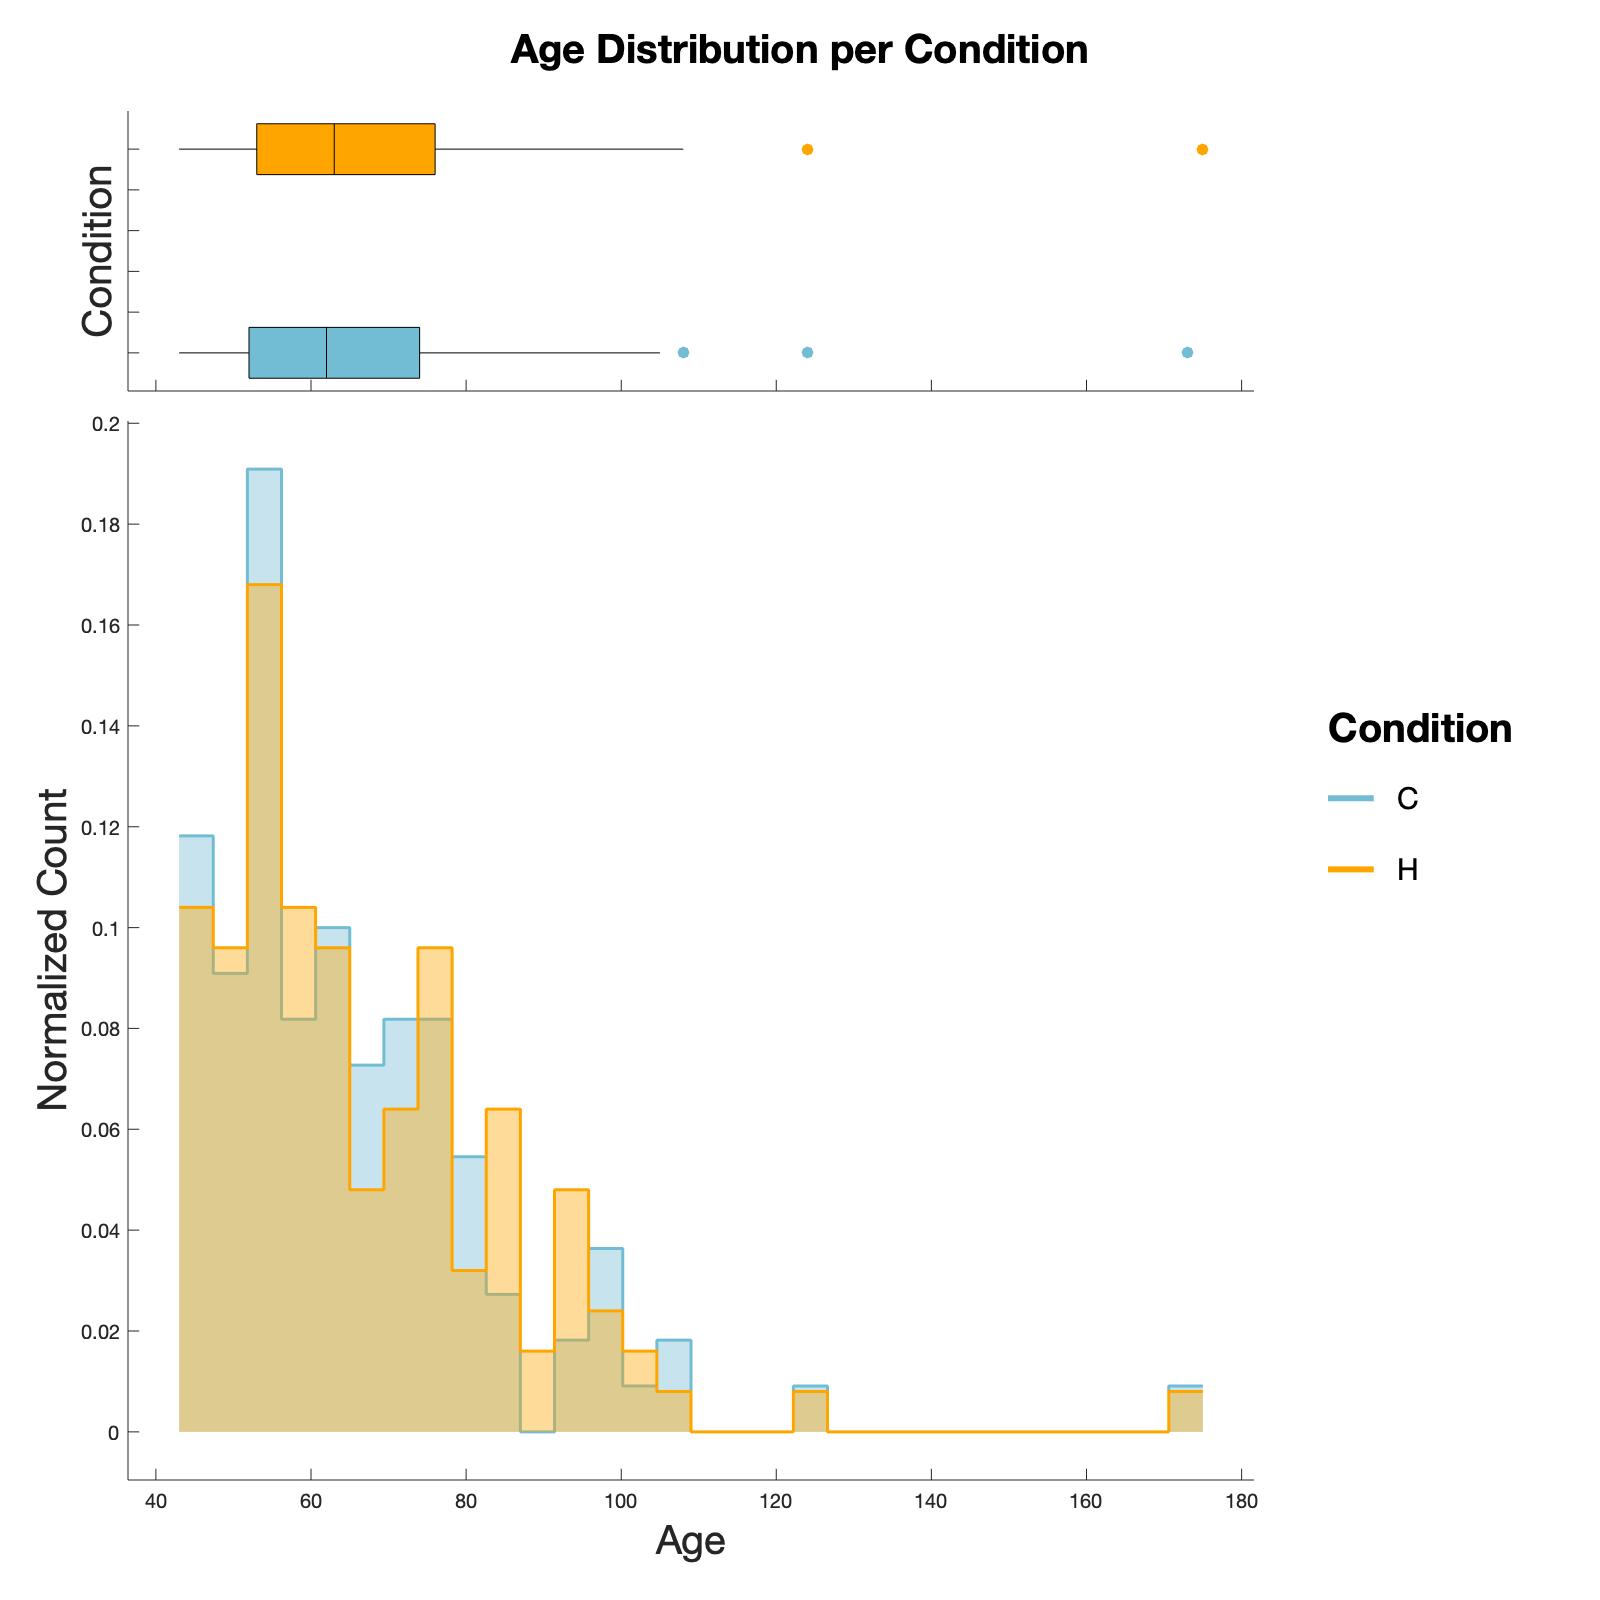

currentFolder='//Users/hannahfarnsworth/Dropbox (HMS)/hyperdata';
cd(currentFolder)


load masterStackTable.mat

1 x 3 same day

c(1,1)=gramm('x',alldataV.AgeAtExp_InjectionStart_days_,'y',alldataV.percFood,'color',alldataV.Condition_H_C_,'subset',alldataV.Day==3)

c =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: []


c(1,1).geom_point()

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


c(1,1).set_names('x','Age','y','Food Intake')

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


c(1,1).no_legend;


c(1,2)=gramm('x',alldataV.AgeAtExp_InjectionStart_days_,'y',alldataV.percTemp,'color',alldataV.Condition_H_C_,'subset',alldataV.Day==3)

c =   1×2 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


c(1,2).geom_point();
c(1,2).set_names('x','Age','y','Temperature')

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


c(1,2).no_legend;


c(1,3)=gramm('x',alldataV.AgeAtExp_InjectionStart_days_,'y',alldataV.percWeight,'color',alldataV.Condition_H_C_,'subset',alldataV.Day==3)

c =   1×3 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


c(1,3).geom_point();
c(1,3).set_names('x','Age','y','Weight','color','Condition')

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


c(1,3).set_layout_options('legend_position',[0.87 0.6 0.2 0.5]);

c.set_color_options('map',[0.447 0.737 0.831 ; 1 0.647 0])

ans =   1×3 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


c.set_title('Physiology Changes Across Ages: Day 3');
figure('Position',[500 500 1500 550]);
c.set_text_options('base_size',10,"big_title_scaling",2.5,'label_scaling',2.5,"legend_scaling",1.5,"legend_title_scaling",1.75)

ans =   1×3 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


c.draw

Custom colormap without n_color and n_lightness specified, defaults to n_lightness=1


Custom colormap without n_color and n_lightness specified, defaults to n_lightness=1


Custom colormap without n_color and n_lightness specified, defaults to n_lightness=1


Custom colormap without n_color and n_lightness specified, defaults to n_lightness=1


ans =   1×3 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


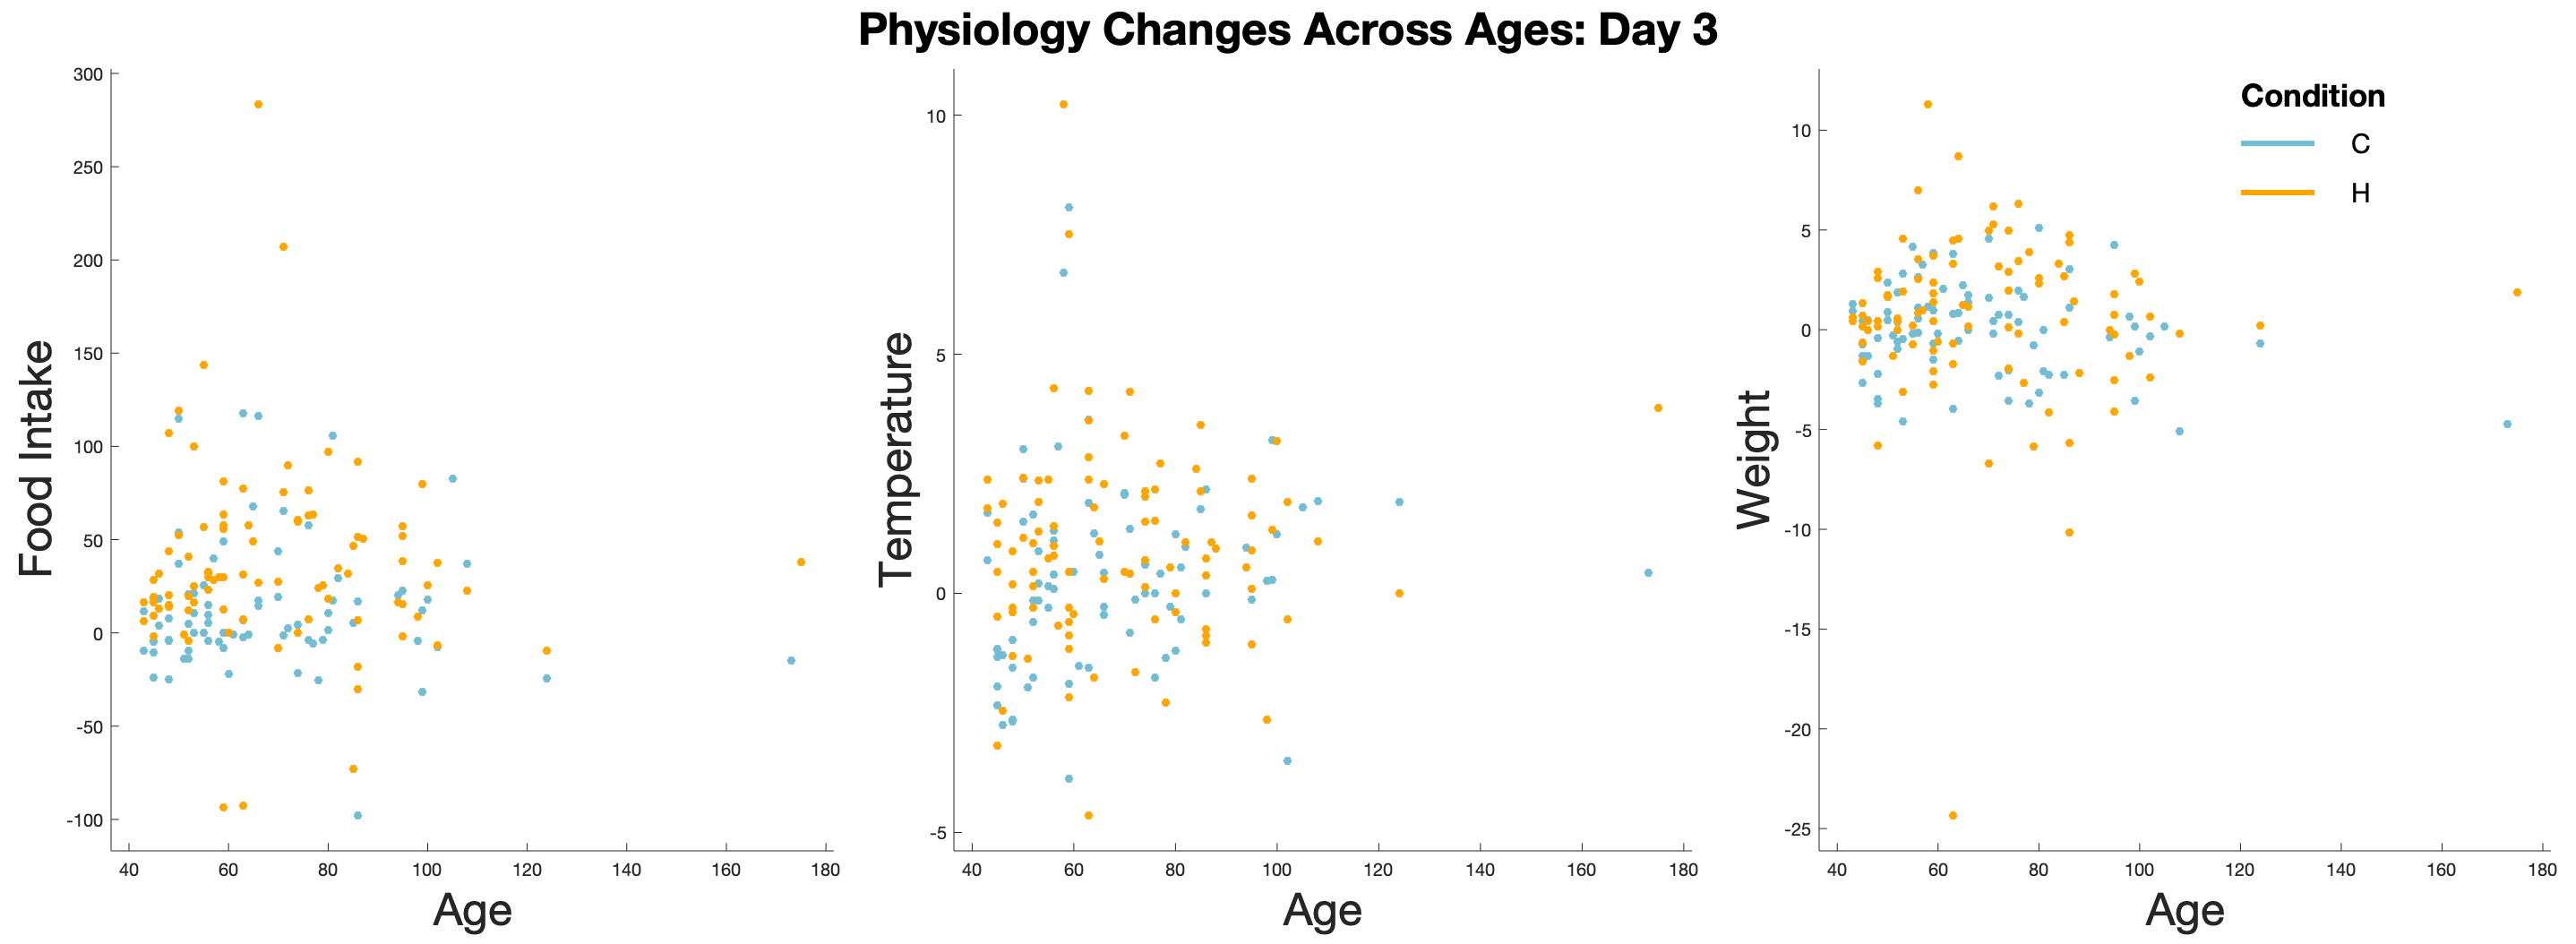


currentFolder='//Users/hannahfarnsworth/Desktop/MTest';
cd(currentFolder)
saveas(gcf,'Age_3Phys_D3','epsc')

Baseline Weight

c=gramm('x',alldataV.AgeAtExp_InjectionStart_days_,'y',alldataV.baselineWeight,'color',alldataV.Condition_H_C_)

c =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: []


c.geom_point();
c.set_names('x','Age','y','Baseline Weight','color','Condition');
c.set_color_options('map',[0.447 0.737 0.831 ; 1 0.647 0])

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


c.set_title('Baseline Weight Across Ages');
figure('Position',[100 100 650 600]);
c.set_text_options('base_size',10,'big_title_scaling',3,'label_scaling',2.5,"legend_scaling",1.5,"legend_title_scaling",1.5)

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


c.draw

Custom colormap without n_color and n_lightness specified, defaults to n_lightness=1


Custom colormap without n_color and n_lightness specified, defaults to n_lightness=1


ans =   gramm with properties:

     legend_axe_handle: [1×1 Axes]
      title_axe_handle: [1×1 Axes]
    facet_axes_handles: [1×1 Axes]
               results: [1×1 struct]


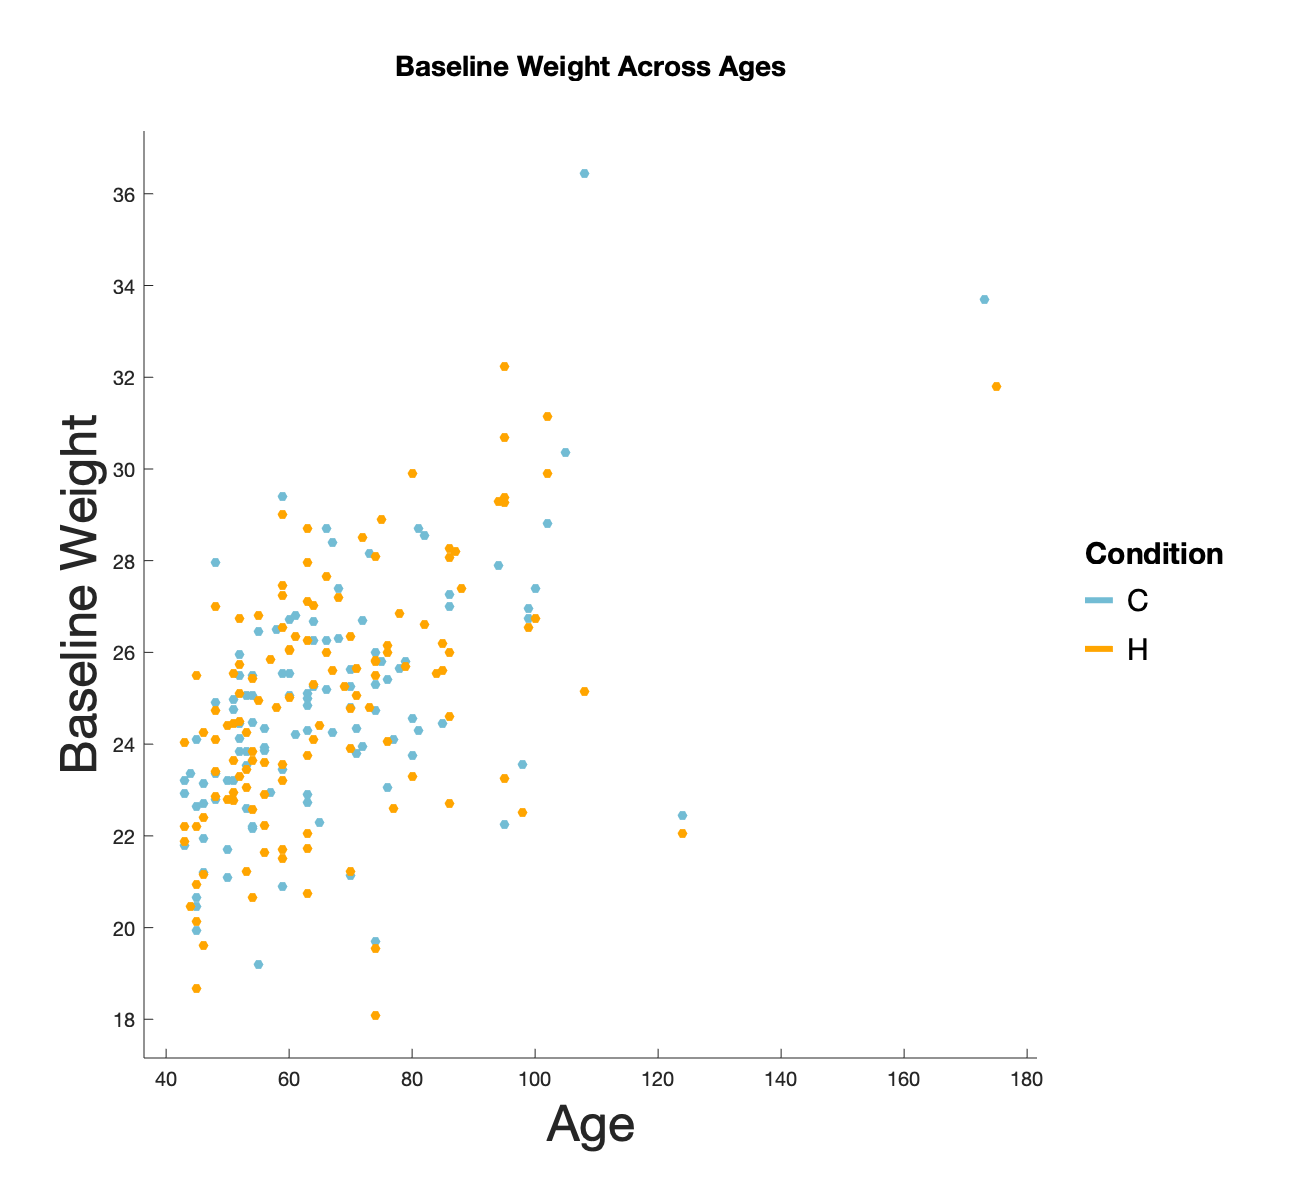


currentFolder='//Users/hannahfarnsworth/Desktop/MTest';
cd(currentFolder)
saveas(gcf,'Age_BaselineWeight','epsc')

3x3 row: measurement, column, day

%Food
c(1,1)=gramm('x',alldataV.AgeAtExp_InjectionStart_days_,'y',alldataV.percFood,'color',alldataV.Condition_H_C_,'subset',alldataV.Day==1)

c =   3×3 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


c(1,1).geom_point()

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


c(1,1).set_names('x','','y','Food Intake')

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


c(1,1).no_legend;
c(1,1).axe_property('YLim',[-120 300],'XLim',[30 180])

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]



c(1,2)=gramm('x',alldataV.AgeAtExp_InjectionStart_days_,'y',alldataV.percFood,'color',alldataV.Condition_H_C_,'subset',alldataV.Day==2)

c =   3×3 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


c(1,2).geom_point();
c(1,2).set_names('x','','y','')

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


c(1,2).no_legend;
c(1,2).axe_property('YLim',[-120 300],'XLim',[30 180])

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]



c(1,3)=gramm('x',alldataV.AgeAtExp_InjectionStart_days_,'y',alldataV.percFood,'color',alldataV.Condition_H_C_,'subset',alldataV.Day==3)

c =   3×3 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


c(1,3).geom_point();
c(1,3).set_names('x','','y','')

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


c(1,3).no_legend;
c(1,3).axe_property('YLim',[-120 300],'XLim',[30 180])

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]



%Temp
c(2,1)=gramm('x',alldataV.AgeAtExp_InjectionStart_days_,'y',alldataV.percTemp,'color',alldataV.Condition_H_C_,'subset',alldataV.Day==1)

c =   3×3 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


c(2,1).geom_point()

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


c(2,1).set_names('x','','y','Temperature')

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


c(2,1).no_legend;
c(2,1).axe_property('YLim',[-5 10],'XLim',[30 180])

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]



c(2,2)=gramm('x',alldataV.AgeAtExp_InjectionStart_days_,'y',alldataV.percTemp,'color',alldataV.Condition_H_C_,'subset',alldataV.Day==2)

c =   3×3 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


c(2,2).geom_point();
c(2,2).set_names('x','','y','')

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


c(2,2).no_legend;
c(2,2).axe_property('YLim',[-5 10],'XLim',[30 180])

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]



c(2,3)=gramm('x',alldataV.AgeAtExp_InjectionStart_days_,'y',alldataV.percTemp,'color',alldataV.Condition_H_C_,'subset',alldataV.Day==3)

c =   3×3 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


c(2,3).geom_point();
c(2,3).set_names('x','','y','')

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


c(2,3).no_legend;
c(2,3).axe_property('YLim',[-5 10],'XLim',[30 180])

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]



%Weight
c(3,1)=gramm('x',alldataV.AgeAtExp_InjectionStart_days_,'y',alldataV.percWeight,'color',alldataV.Condition_H_C_,'subset',alldataV.Day==1)

c =   3×3 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


c(3,1).geom_point()

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


c(3,1).set_names('x','  ','y','Weight')

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


c(3,1).no_legend;
c(3,1).axe_property('YLim',[-15 15],'XLim',[30 180])

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]



c(3,2)=gramm('x',alldataV.AgeAtExp_InjectionStart_days_,'y',alldataV.percWeight,'color',alldataV.Condition_H_C_,'subset',alldataV.Day==2)

c =   3×3 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


c(3,2).geom_point();
c(3,2).set_names('x','Age','y','')

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


c(3,2).no_legend;
c(3,2).axe_property('YLim',[-15 15],'XLim',[30 180])

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]



c(3,3)=gramm('x',alldataV.AgeAtExp_InjectionStart_days_,'y',alldataV.percWeight,'color',alldataV.Condition_H_C_,'subset',alldataV.Day==3)

c =   3×3 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


c(3,3).geom_point();
c(3,3).set_names('x','   ','y','','color','Condition')

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


c(3,3).no_legend;
c(3,3).set_layout_options('legend_position',[0.9 0.65 0.2 0.5])

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


c(3,3).axe_property('YLim',[-15 15],'XLim',[30 180])

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]




c.set_color_options('map',[0.447 0.737 0.831 ; 1 0.647 0])

ans =   3×3 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


c.set_title('Physiology Changes with Age Across Treatment');
figure('Position',[0 0 900 900]);
c.set_text_options('base_size',10,"big_title_scaling",2.5,'label_scaling',2.5,"legend_scaling",1.5,"legend_title_scaling",1.75)

ans =   3×3 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


c.draw

Custom colormap without n_color and n_lightness specified, defaults to n_lightness=1


Custom colormap without n_color and n_lightness specified, defaults to n_lightness=1


Custom colormap without n_color and n_lightness specified, defaults to n_lightness=1


Custom colormap without n_color and n_lightness specified, defaults to n_lightness=1


Custom colormap without n_color and n_lightness specified, defaults to n_lightness=1


Custom colormap without n_color and n_lightness specified, defaults to n_lightness=1


Custom colormap without n_color and n_lightness specified, defaults to n_lightness=1


Custom colormap without n_color and n_lightness specified, defaults to n_lightness=1


Custom colormap without n_color and n_lightness specified, defaults to n_lightness=1


Custom colormap without n_color and n_lightness specified, defaults to n_lightness=1


ans =   3×3 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


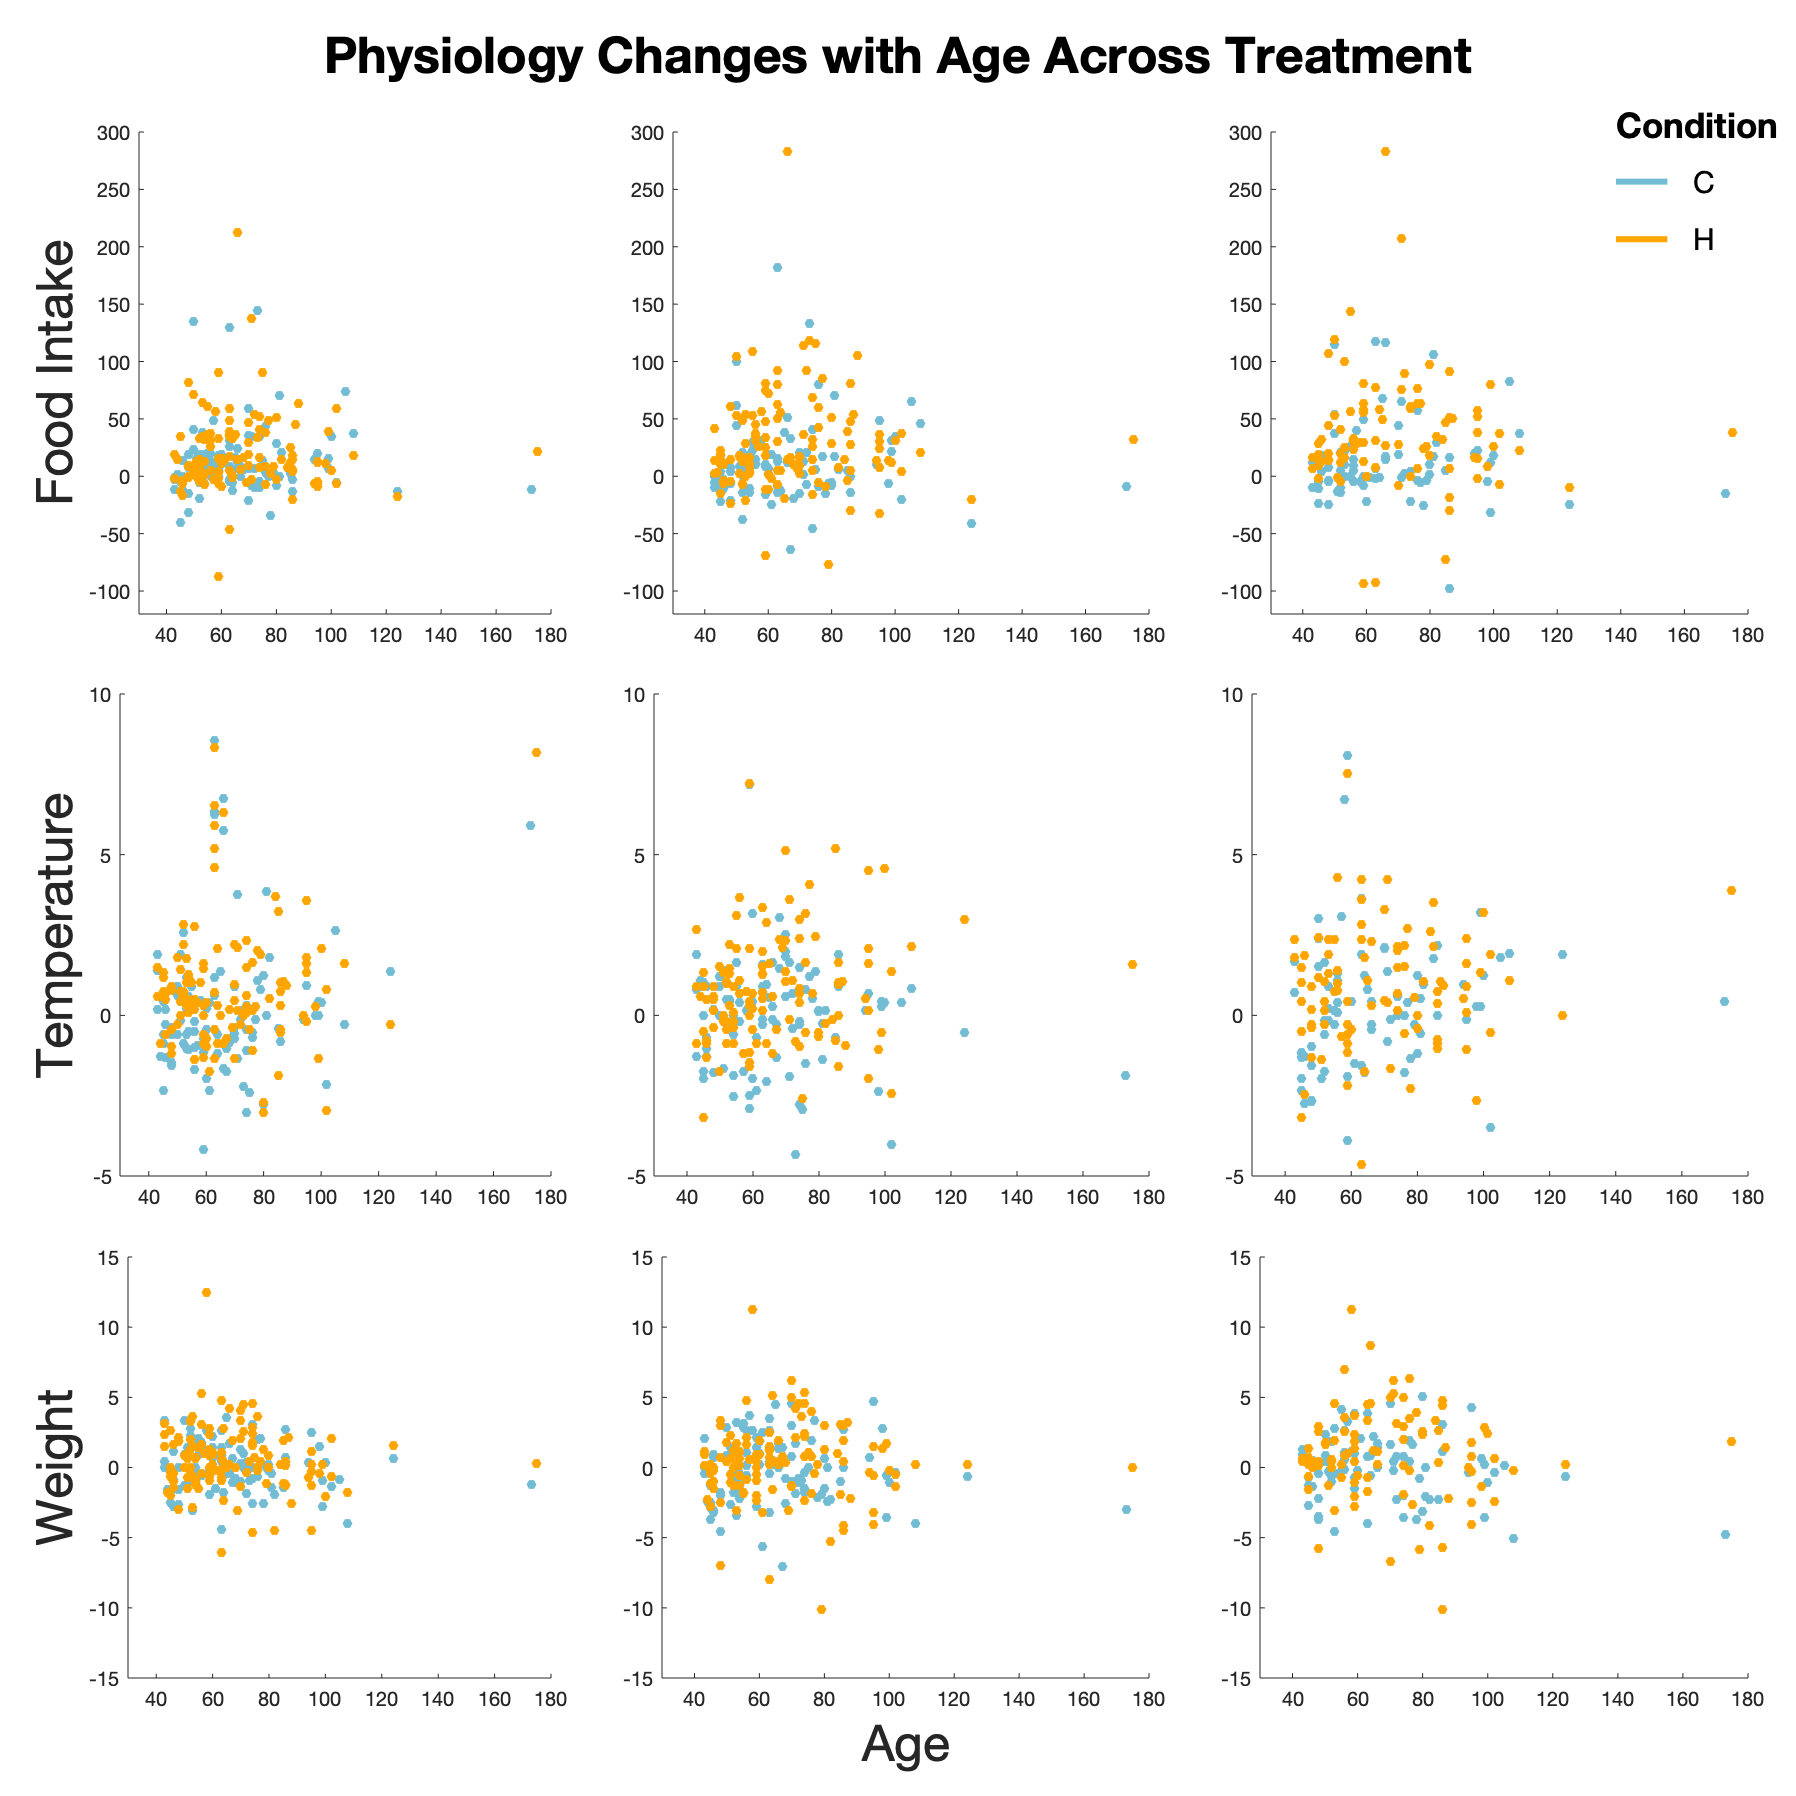


currentFolder='//Users/hannahfarnsworth/Desktop/MTest';
cd(currentFolder)
saveas(gcf,'Age_All6','epsc')